code 1

% Step 1: Signal Processing to Generate Images
% Select the .mat file
[file, path] = uigetfile('*.mat', 'Select the MAT-file');
if isequal(file, 0)
    error('No file selected.');
else
    data = load(fullfile(path, file));
end

No file selected.


% Select the output directory for processed images
outputDir = uigetdir('Select the output directory');
if isequal(outputDir, 0)
    error('No output directory selected.');
end

% Get variable names from the loaded file
varNames = fieldnames(data);

% Define signal parameters
signallength = 25600;
fb = cwtfilterbank('SignalLength', signallength, 'Wavelet', 'amor', 'VoicesPerOctave', 48);

% Process each signal variable in the .mat file
for i = 1:length(varNames)
    varName = varNames{i};
    signal = data.(varName).Variables; % Assuming timetable variable contains the signal
    mkdir(fullfile(outputDir, varName)); % Create folder for each variable
    bf2cwtscg(signal, fb, varName, outputDir);
end
% Function definition for processing
function bf2cwtscg(bfdata, cwtfb, bftype, outputDir)
    % Segment parameters
    win_len = 25600; % Length of each segment
    stride = 2560;  % Step size for sliding window (adjust as needed)
    colormap = jet(256);

    % Get folder path based on type
    folderpath = fullfile(outputDir, bftype);

    % Calculate number of segments based on stride
    num_segments = floor((length(bfdata) - win_len) / stride) + 1;

    % Loop through segments and process
    for k = 1:num_segments
        start_idx = (k-1)*stride + 1;        % Starting index for the segment
        end_idx = start_idx + win_len - 1;  % Ending index for the segment

        if end_idx > length(bfdata)
            break; % Ensure we don't exceed signal length
        end

        % Extract segment
        bfsignal = bfdata(start_idx:end_idx); 

        % Perform Continuous Wavelet Transform (CWT) and process
        cfs = abs(cwtfb.wt(bfsignal));          % Perform CWT and get absolute value
        im = ind2rgb(im2uint8(rescale(cfs)), colormap); % Rescale and convert to image
        im = im - min(im(:));                   % Normalize
        im = im / max(im(:));                   % Normalize
        im = imresize(im, [227 227]);           % Resize image

        % Save image
        filename = fullfile(folderpath, sprintf('%d.jpg', k)); % Generate filename
        imwrite(im, filename); % Save normalized image
    end
end

code 2

Accuracy for inner_ring_lt: 100.00%
Accuracy for dddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddd: 

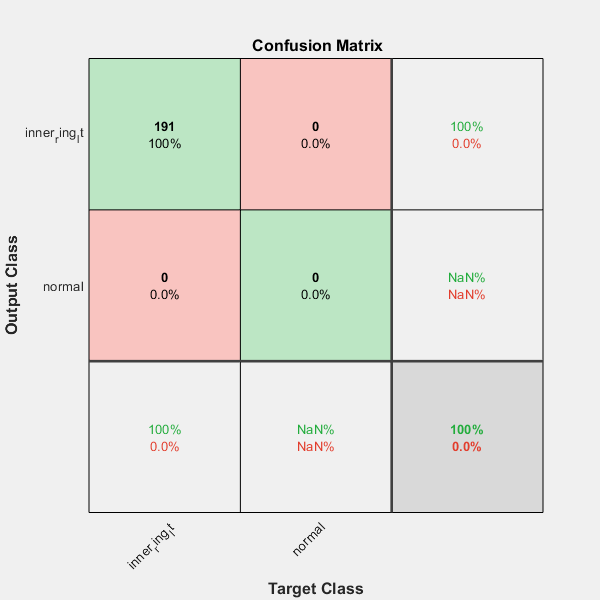

Accuracy for normal: 100.00%
Accuracy for dddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddddd: 

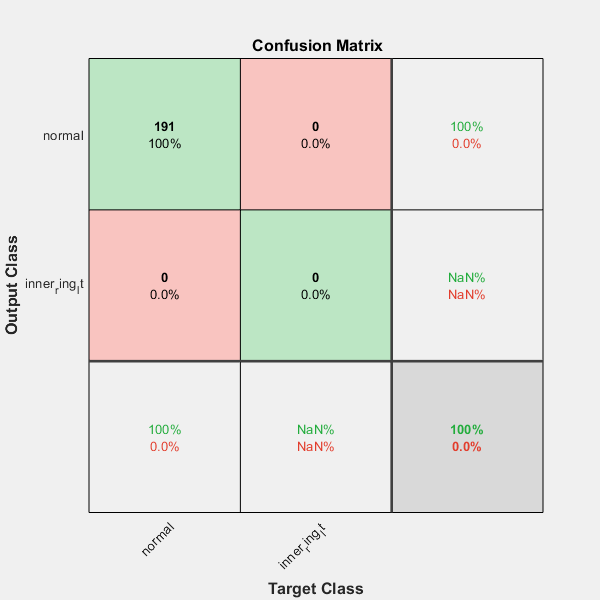

% Step 2: ML Model Prediction
% Load the trained model
load('trainedModel.mat', 'netTransfer');

% List all subfolders in the output directory
subfolders = dir(outputDir);
subfolders = subfolders([subfolders.isdir] & ~startsWith({subfolders.name}, '.')); % Ignore hidden/system folders

% Iterate through each subfolder
for i = 1:length(subfolders)
    % Get the current subfolder path
    imageFolder = fullfile(outputDir, subfolders(i).name);
    
    % Create an ImageDatastore for this subfolder
    newImages = imageDatastore(imageFolder, 'FileExtensions', {'.jpg'});

    % Predict labels for images in the subfolder
    predictedLabels = classify(netTransfer, newImages);

    % Define ground truth labels (e.g., based on subfolder name)
    trueLabels = categorical(repmat({subfolders(i).name}, 1, numel(predictedLabels)));

    % Calculate accuracy
    accuracy = sum(predictedLabels == trueLabels) / numel(trueLabels);
    fprintf('Accuracy for %s: %.2f%%\n', subfolders(i).name, accuracy * 100);

    % Display confusion matrix for this subfolder in a separate window
    figure; % Create a new figure for each subfolder

    % Optional: Display confusion matrix for this subfolder
    plotconfusion(trueLabels', predictedLabels);
end